bostonh房价综合分析

clc
load bostonh.txt
idea=[0.0063,80,0.46,1,0.385,8.78,2.9,1.1296,24,187,12.6,0.32,1.73,5]

idea =     0.0063   80.0000    0.4600    1.0000    0.3850    8.7800    2.9000    1.1296   24.0000  187.0000   12.6000    0.3200    1.7300    5.0000


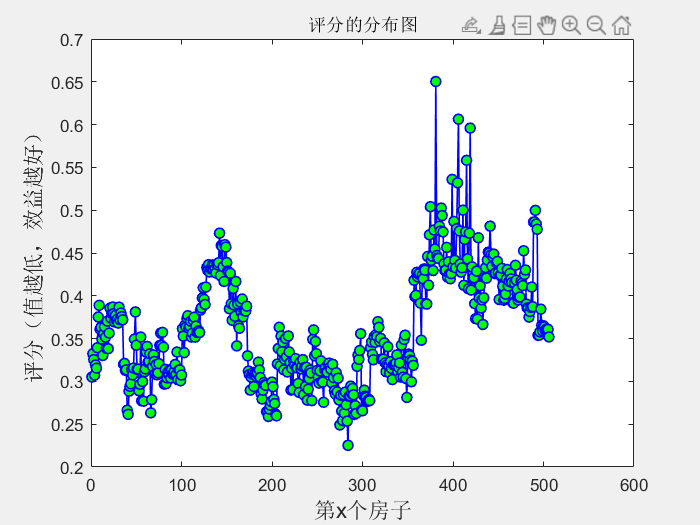

% num=[1,4,5,6,8,9,10,11,12,13]
num=1:14;
% num=1:14
m=fbostonh(bostonh,num,idea)
figure("Visible","on");
plot(m,"Color","b","LineStyle","-","LineWidth",1,"Marker","o","MarkerFaceColor","g");
ylabel("评分（值越低，效益越好）","FontSize",13);
xlabel("第x个房子","FontSize",13);
title("评分的分布图");
hold on;
n=1:506;
% text(n,m,""+m(n,1))
hold off;

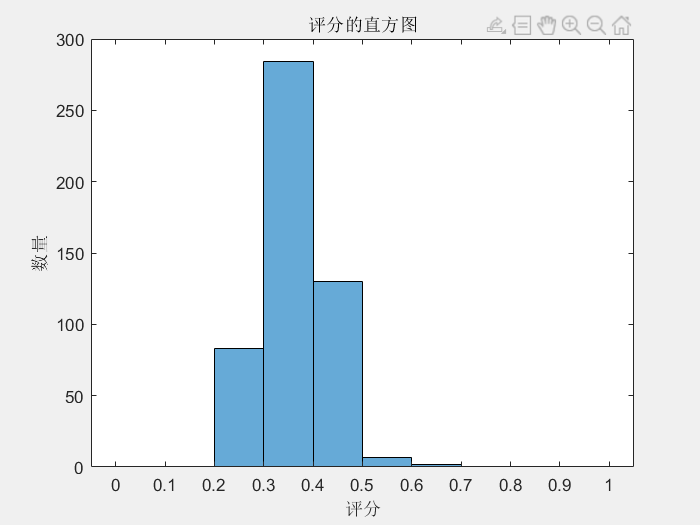

figure("Visible","on");
histogram(m,0:0.1:1);
hold on;
title("评分的直方图");
xlabel("评分");
ylabel("数量");
hold off

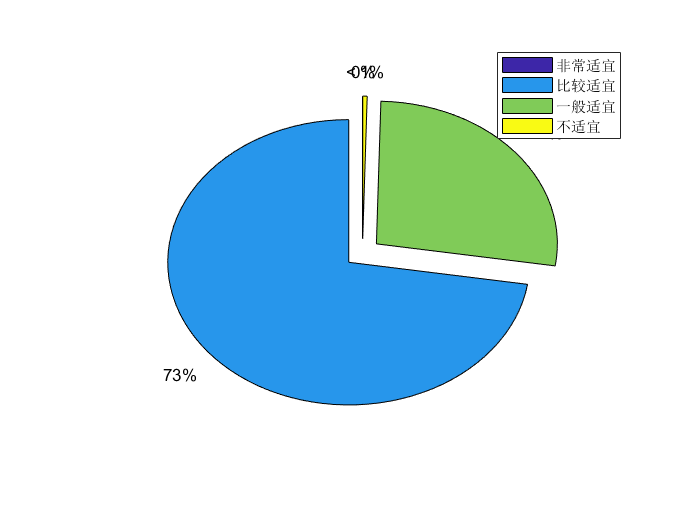

% xlim([-0.050 1.050])
% ylim([0.1 35.1])
% pie(F);
figure
txt={'非常适宜','比较适宜','一般适宜','不适宜'};
txt_num=[0,0,0,0];
for i=1:506
   if m(i)<=0.2
       txt_num(1)=txt_num(1)+1;
   elseif m(i)<=0.4
       txt_num(2)=txt_num(2)+1;
   elseif m(i)<=0.6
       txt_num(3)=txt_num(3)+1;
   else
       txt_num(4)=txt_num(4)+1;
   end
end
hold on;

explode=[1,1,1,1];
pie(txt_num,explode);
legend(txt);
axis off